# Experiment Set #38.

The goal of the experiment is to identify how robust optimization can be done to find minimal zonotope representation.

% Add experiments and functions to the path
include_fcns('MPT3','YALMIP')

All Libraries successfully added to path.


Creating a set that we want to enclose with an arbitrary zonotope.

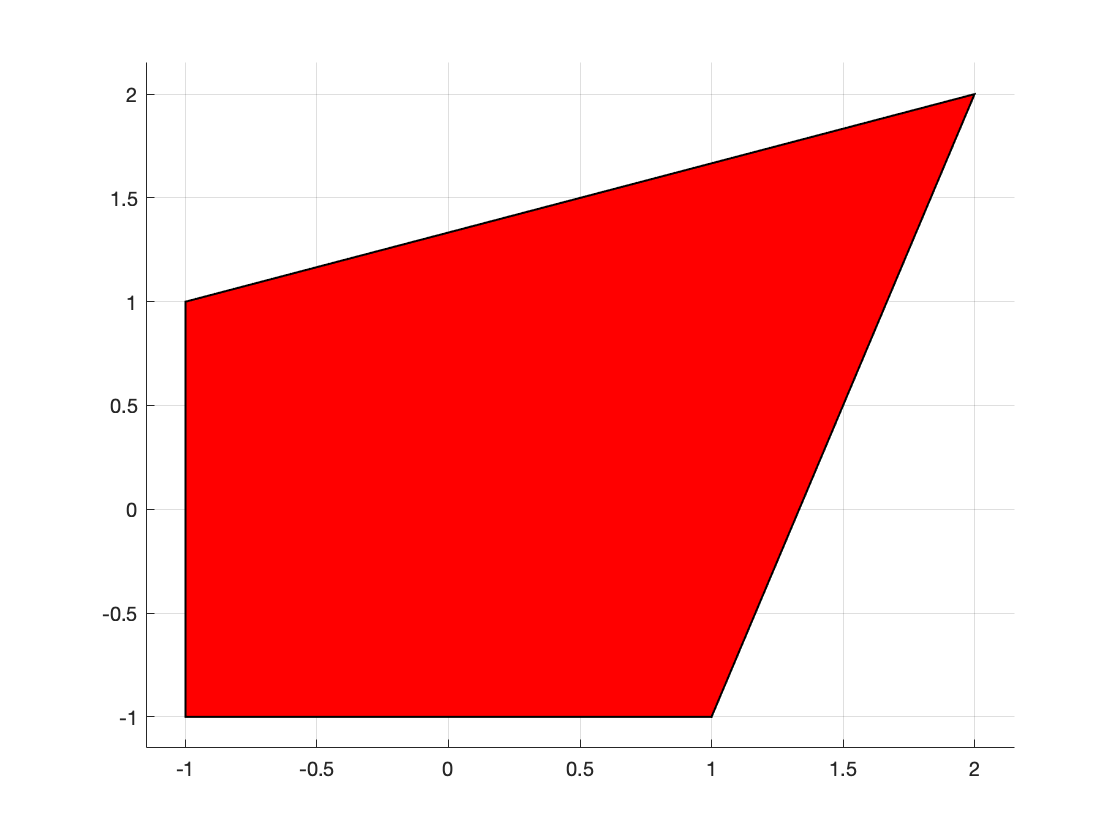

P_e = Polyhedron('A', [ 0 , -1; -1, 0; -(1/3), 1; 3, -1 ], ...
                 'b', [1;1;(4/3);4]);
figure;
plot(P_e)

Create a zonotope template. We will control the scaling of the generators to control its size in optimization. A traditional zonotope might be:


$$$\mathcal{Z} = \left\{ x \in \mathbb{R}^2 \left| \exists \theta \; \text{ s.t. } x = c + G\theta \wedge (|\theta_i| \leq 1 \; \forall i) \right. \right\}$
$$


And so we seek to find a modified zonotope of the following form:


$$$\mathcal{Z}_{\alpha} = \left\{ x \in \mathbb{R}^2 \left| \exists \theta \; \text{ s.t. } x = c + G\theta \wedge (|\theta_i| \leq \alpha \; \forall i) \right. \right\}$
$$


Z_t.c = zeros(2,1);
%Z_t.G = [ [1;0] [0;1] ];
%Z_t.G = [ [1;1]*(1/sqrt(2)), [0;1] ]
Z_t.G = [ [2;2], [1;-1] ]

Z_t = struct with fields:
    c: [2×1 double]
    G: [2×2 double]


With all of this, we can state the formal problem that we want to solve:


$$\begin{array}{rl}
  \underset{\alpha}{\text{min}} & \alpha \\
  \text{subject to} & \mathcal{P}_w \subseteq \mathcal{Z}_{\alpha}
\end{array} $$


This can be stated in the following way:


$$\begin{array}{rl}
  \underset{\begin{array}{c} \alpha \in \mathbb{R} \end{array}}{\text{min}} & \alpha \\
  \text{subject to} & \exists \theta \text{ such that } w = c + G \theta \text{ for any } w \in \mathcal{P}_w
\end{array} $$


In a more mathematical construction:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i | \leq 1 & \forall i \in {1,2} \\ & w = c +\alpha G \theta & \forall w \in \mathcal{P}_w
\end{array} $$


This is in fact a robust optimization problem and I think that we can apply the following robust optimization to solve the problem:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i | \leq 1 & \forall i \in {1,2} \\ & w \leq c +\alpha G \theta & \forall w \in \mathcal{P}_w \\
  & -w \leq -c - \alpha G \theta & \forall w \in \mathcal{P}_w
\end{array} $$


This can be written in the following "pseudo" optimization:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta^{(1)},\theta^{(2)} \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i^{(j)} | \leq 1 & \forall i,j \in {1,2} \\
 & \left[
             \begin{array}{rll}
                \underset{w\in P_w}{\text{"max"}} &  w^\top (G^\dagger)^\top &  \\
                \text{such that} & Aw \leq b
             \end{array}
     \right] \leq c +\alpha G \theta_1 & \\
 & \left[
             \begin{array}{rll}
                \underset{w\in P_w}{\text{"max"}} &  w^\top (-G^\dagger)^\top &  \\
                \text{such that} & Aw \leq b
             \end{array}
     \right] \leq -c -\alpha G \theta_1 & \\\end{array} $$


%Define Optimization Variables
alpha = sdpvar(1,1,'full');
theta_t1 = sdpvar(size(Z_t.G,2),1,'full');
theta_t2 = sdpvar(size(Z_t.G,2),1,'full');
p1 = sdpvar(size(P_e.A,1),size(Z_t.G,1),'full');
p2 = sdpvar(size(P_e.A,1),size(Z_t.G,1),'full');

%Create Objective
objective = alpha;

%Create Constraints
equal_constrs = [p1'*P_e.b <= theta_t1 + pinv(Z_t.G)*Z_t.c] + ...
                [p2'*P_e.b <= -theta_t2 - pinv(Z_t.G)*Z_t.c];
dual_equal_constrs = [];
dual_equal_constrs = [P_e.A'*p1 == (pinv(Z_t.G))'] + ...
                     [P_e.A'*p2 == (-pinv(Z_t.G))'];
                 
dual_pos_constrs = [p1 >= 0] + [p2 >= 0];

%
inf_norm_constr = [ theta_t1 <= alpha ] + [-theta_t1 <= alpha] + ...
                  [ theta_t2 <= alpha ] + [-theta_t2 <= alpha];

%Optimize
ops = sdpsettings('verbose',1);
optim0 = optimize(equal_constrs+dual_equal_constrs+dual_pos_constrs+inf_norm_constr, ...
			objective, ...
			ops);
if optim0.problem ~= 0
    disp(['Optimization failed with "problem" value: ' num2str(optim0.problem)])
else
    disp('Optimization seems to have been successful.')
    disp(['alpha = ' num2str(value(alpha))])
end

%Optimal Scaling factor
sf = value(alpha)